# ランダムウォーク

乱数を統計物理学に用いたシミュレーションとして、ランダムウォークを紹介する。

clear all; clf;

## 1次元 random walk

まず $x$ 軸上を運動する粒子のランダムウォークを考える。

このモデルでは時刻 $t$ における粒子の座標 $x(t)$ を、次式に従って時間の1ステップごとに更新する。


$$x(t+1) = x(t) + r(t)$$


ただし、 $x(0)=0$、 $r(t)$ は $-1$からから $+1$までの一様乱数とする。

Q1. $x(t)$の時系列を $0\leq t \leq 1000$の範囲でプロットせよ。

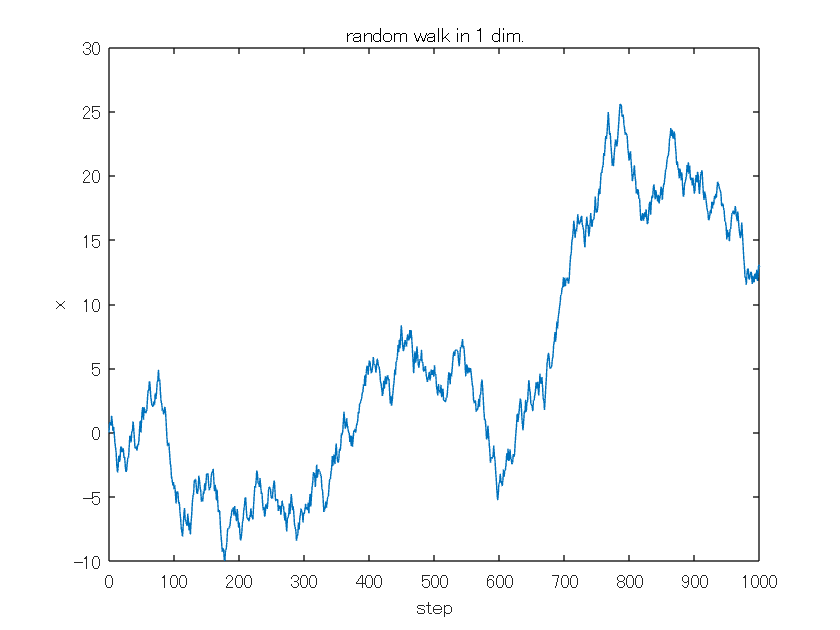

%random walk in 1 dim.
T = 1000;
tm = 0:1:T;
r = 2*(rand(1, T)-0.5);
x = [0 cumsum(r,2)];

%plot a time series 
plot(tm, x, '-')
xlabel('step')
ylabel('x')
title('random walk in 1 dim.')

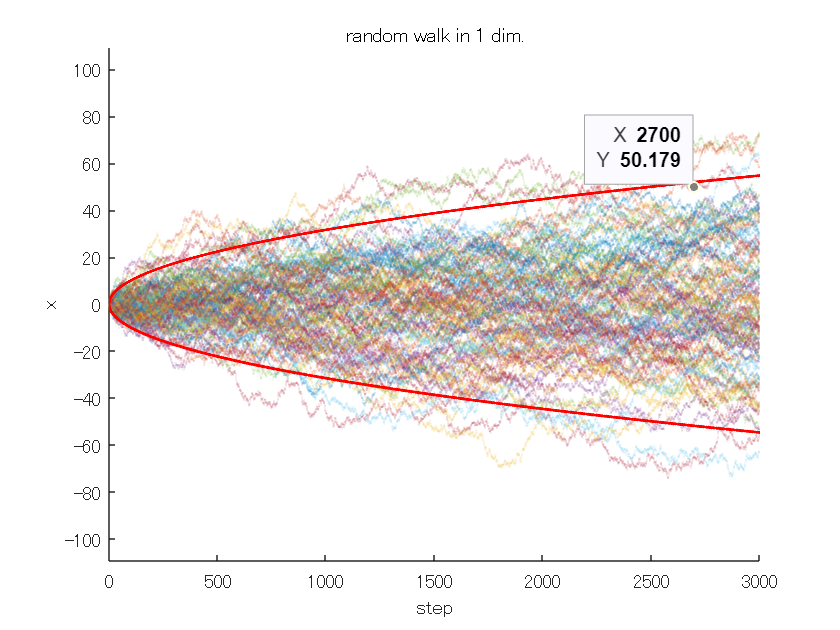

%random walk in 1 dim.
T = 3000;
tm = 0:1:T;
r = 2*(rand(1, T)-0.5);
x = [0 cumsum(r,2)];

%plot a time series 
alp = 0.1;
scatter(tm, x, 1, 'filled', MarkerEdgeAlpha=alp, MarkerFaceAlpha=alp);
hold on 
for it = 1:100
    r = 2*(rand(1, T)-0.5);
    x = [0 cumsum(r,2)];
    scatter(tm, x, 1, 'filled', MarkerEdgeAlpha=alp, MarkerFaceAlpha=alp);
end

plot(tm, sqrt(tm), 'r-', LineWidth=1.5)
plot(tm, -sqrt(tm), 'r-', LineWidth=1.5)
ylim([-2*sqrt(T) 2*sqrt(T)]);
xlim([0 T])


hold off
xlabel('step')
ylabel('x')
title('random walk in 1 dim.')

### 1次元 random walk: x(t) の分布

Q2. Q1で考えた1次元ランダムウォーク $x(t)$について、 $x(500)$を10000個求め、それらの度数分布を描画せよ。

note: この結果は正規分布でフィッティングできる。

時刻 $t$ において粒子が位置 $x$ に存在する確率密度は正規分布 (ガウス分布)


$$P(x,t)=
\frac{1}{\sqrt{4\pi Dt}}\exp \left( -\frac{x^2}{4Dt} \right)
$$


の形をとる。

(粒子数密度の分布は粒子数 $N(=10000)$ を用いて $f(x,t)=NP(x,t)$ と表される。)

グラフを見ると、確かに $T=500$ での粒子数密度の分布が正規分布によって良くフィッティングできている。

%random walk 
N = 10000;
T = 500;
%r = sign(rand(N, T)-0.5);
r = 2*(rand(N, T)-0.5);
x = cumsum(r,2);

binwidth = 2;
nbins = [-T-1:binwidth:T+1];
%H = histogram(x(:, T), nbins)
H1 = histcounts(x(:, T), nbins);


統計性 (分布のフィッティング)

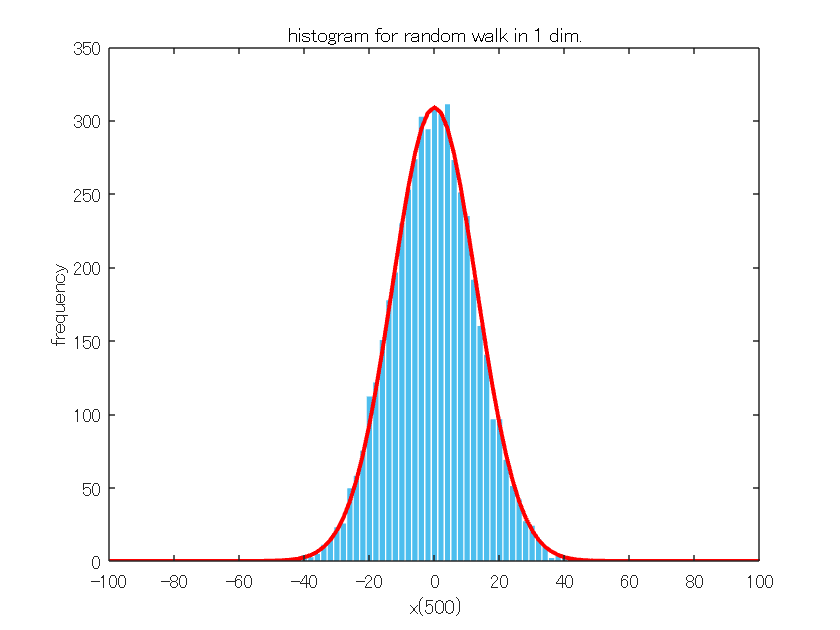

x0 = [-T:binwidth:T];
bar (x0, H1/binwidth ,EdgeColor="none", FaceColor='#4DBEEE');
%bar (x0, H.Values/H.BinWidth, 'green' ,EdgeColor="none")
%plot(x0, H.Values/H.BinWidth) %binの幅で割り，粒子数密度にする
D = 1/6;
y0 = (N/sqrt(4*pi*D*T)) * exp(-x0.*x0/(4*D*T));
hold on
plot(x0, y0, 'r', LineWidth=2)
xlim([-T/5 T/5])
%ylim([0 400])
xlabel('x('+string(T)+')')
ylabel('frequency')
title('histogram for random walk in 1 dim.')
hold off

### 1次元 random walk: x(t) の分散の時間変化

各時刻 $t$ における $N$ 個の粒子の位置 $x_{j}(t)$の分散を求め、グラフに表し、分散が時間に対して比例していることを確かめる。

ランダムウォークの歩幅を $a$とすると、分散と時刻の比例係数は $a^2$ となる。

いま、粒子の変位は $[-1,1]$ の区間の一様乱数を用いており、一様乱数の標準偏差は $\frac{1}{\sqrt{3}}$ であり、この値が歩幅 $a$に相当する。従って、比例係数は $a^2=\frac{1}{3}$ となることが期待される。

%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( [], var(x) );

% 近似タイプとオプションを設定します。
ft = fittype( 'poly1' );

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft )

fitresult =      線形モデル Poly1:
     fitresult(x) = p1*x + p2
     係数 (95% の信頼限界):
       p1 =      0.3293  (0.3288, 0.3297)
       p2 =      0.1554  (0.02963, 0.2812)

gof = フィールドをもつ struct :
           sse: 254.3082
       rsquare: 0.9998
           dfe: 498
    adjrsquare: 0.9998
          rmse: 0.7146


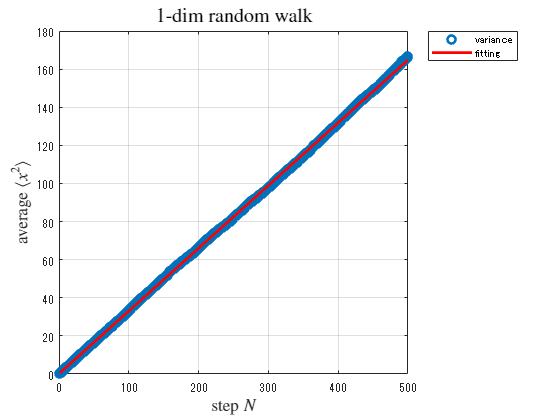


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot(xData, yData,'o', xData, fitresult(xData), 'r-', LineWidth=2);
legend( h, 'variance', 'fitting', 'Location', 'bestoutside' , 'Interpreter', 'none' );
% ラベル Axes
xlabel('step $N$', Interpreter='latex', FontSize=13);
ylabel('average $\langle x^2 \rangle$', Interpreter='latex', FontSize=13);
title("1-dim random walk", Interpreter="latex", FontSize=15);
grid on

## 2次元 random walk

次に $xy$ 平面上を運動する粒子のランダムウォークを考える。

1次元の場合と同様、時刻 $t$ における粒子の座標 $(x(t),y(t))$ を次式に従って更新する。


$$x(t+1) = x(t) + r(t)\\
y(t+1) = y(t) + s(t)$$


ただし、 $\left(x(0), y(0))=(0, 0)$、 $r(t), s(t)$ は $-1$からから $+1$までの一様乱数とする。

Q3. 軌跡 $\left(x(t), y(t))$を $0\leq t \leq 1000$の範囲でプロットせよ。

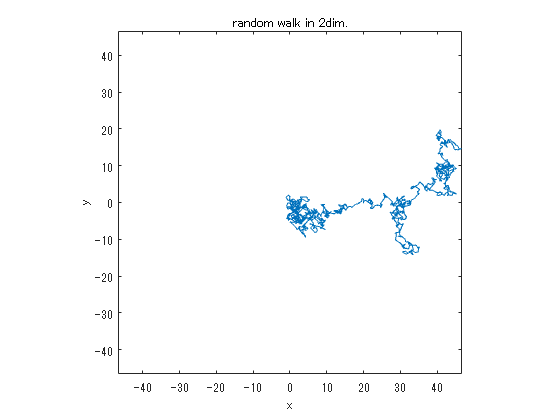

%random walk 
T = 1000;
r = 2*(rand(1, T)-0.5);
s = 2*(rand(1, T)-0.5);
wx = [0 cumsum(r,2)];
wy = [0 cumsum(s,2)];

%plot a time series 
bb = max([max([wx, wy]), -min([wx, wy])]);

plot(wx, wy)
xlim([-bb bb])
ylim([-bb bb])
% 図の縦横比を１：１にする
pbaspect([1 1 1])
title('random walk in 2dim.')
xlabel('x')
ylabel('y')

clf;

### ランダムウォークするN粒子の空間分布 (散布図)とガウス分布によるフィッティング（リアルタイム）

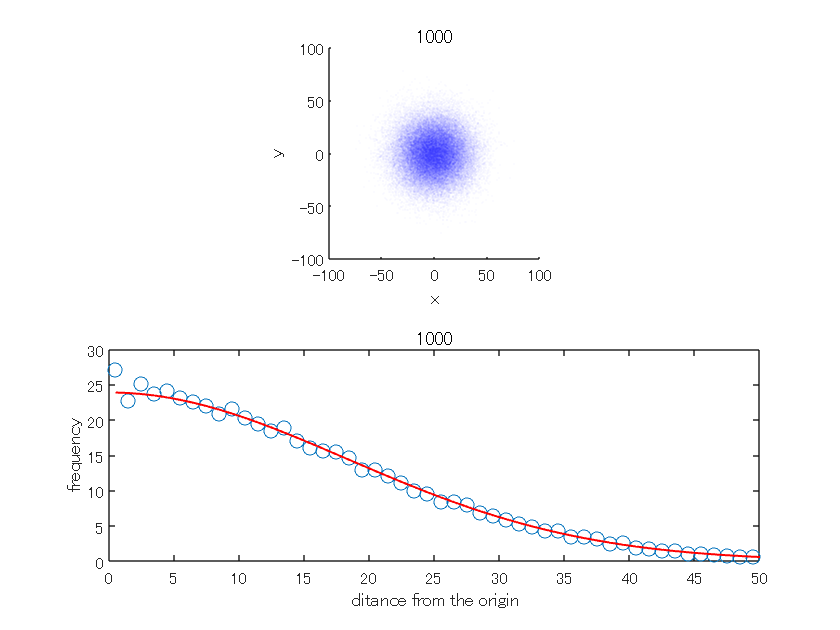

clf;
N = 50000;
T = 1000;
px = zeros(1,N);
py = zeros(1,N);
vs = zeros(1,T);

%hold on 

for j = 1:1:T+1
    if rem(j,10)==1
        tiledlayout(2,1) % Requires R2019b or later
        nexttile
        s=scatter(px, py, 1,'blue', 'filled');
        s.AlphaData = 0.2;
        s.MarkerFaceAlpha = 0.02;
        xlim([-100 100])
        ylim([-100 100])
        xlabel('x')
        ylabel('y')
        pbaspect([1 1 1])
        title(j-1)

        nexttile
        ds = sqrt(px.*px + py.*py);
        binwidth = 1;
        nbins = [0:binwidth:T];
        h2 = histcounts(ds, nbins);
        x2 = binwidth * ([1:binwidth:T]-0.5*binwidth);
        y2 = h2/(2*pi)./x2/binwidth;
        plot(x2, y2, 'o', MarkerSize=7);
        xlim([0 50])
        %ylim([0 10000])
        D = 1/6;
        y2p = (N/(4*pi*D*j)) * exp(-x2.*x2/(4*D*j));
        hold on
        plot(x2, y2p, 'r', LineWidth=1);
        title(j-1);
        xlabel('ditance from the origin')
        ylabel('frequency')
        
        hold off
        xh2((j-1)/10+1,:) = y2;
        drawnow
    end
    px = px + 2*(rand(1, N)-0.5);
    py = py + 2*(rand(1, N)-0.5);
    vs(j) = mean(px.*px + py.*py);
end

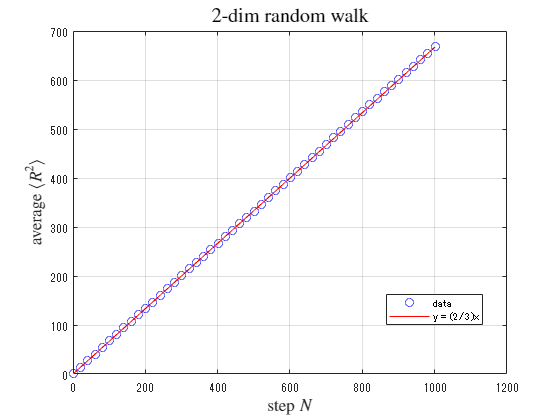

clf;
st = 1:T+1;
plot(st(1:20:end), vs(1:20:end), 'bo', DisplayName="data")
hold on
plot(st, (2/3)*st,'r-', DisplayName="y = (2/3)x")

% ラベル Axes
xlabel('step $N$', Interpreter='latex', FontSize=13);
ylabel('average $\langle R^2 \rangle$', Interpreter='latex', FontSize=13);
legend(Location="best")
title("2-dim random walk", Interpreter="latex", FontSize=15);
grid on
hold off

### 統計性 (分布のフィッティング)

2次元のランダムウォークにおいても、位置 $\vec{r}=(x,y)$ に粒子が存在する確率密度はガウス分布


$$P(\vec{r},t)=P(x,t)P(y,t)=\frac{1}{4\pi Dt}\exp \left( -\frac{r^2}{4Dt} \right)
\qquad
(r=|\vec{r}|)$$


になる (ただし $P(x,t)$ は1次元の場合の確率密度)。

そこで粒子数密度 $f(\vec{r},t)=NP(\vec{r},t)$ ($N$は粒子数) を $r(\ge 0)$ に対して描画すると、確かに粒子の空間分布のデータはグラフのように、ガウス分布を用いて良くフィッテイングできる。

ただしフィッティングの際には、上記のガウス分布において $D=\frac{1}{6}$  と選んである。

$D=\frac{1}{6}$ となる理由は以下のように考えられる。

1ステップあたりの歩幅を $a$ とすると、ランダムウォークでは $t$ ステップ後の分布の分散は $ta^{2}$ で与えられるので、式中の $D$ に相当する量は


$$D = \frac{a^{2}}{2}$$


と同定される。

そこで本モデルにおける歩幅 $a$ の値を考える。

ここでは粒子の変位の$x$成分、$y$成分それぞれに $[-1,1]$ の区間の一様乱数を用いており、一様乱数の標準偏差は $\frac{1}{\sqrt{3}}$ になる。

従って、一回のランダムウォークにおける歩幅 $a$ は$a = \frac{1}{\sqrt{3}}\times \sqrt{2}=\sqrt{\frac{2}{3}}$

となる。

以上よりパラメーター $D$ は


$$D = \frac{a^{2}}{2} = \frac{1}{6}$$


と求まる。

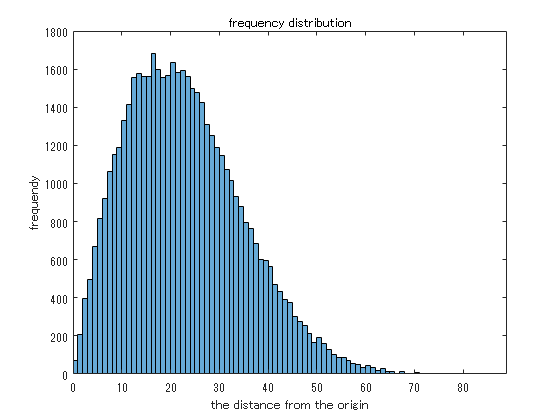

tiledlayout(1,1)

ds = sqrt(px.*px + py.*py);
h = histogram(ds);
xlabel('the distance from the origin')
ylabel('frequendy')
title('frequency distribution')
xlim([0 Inf])

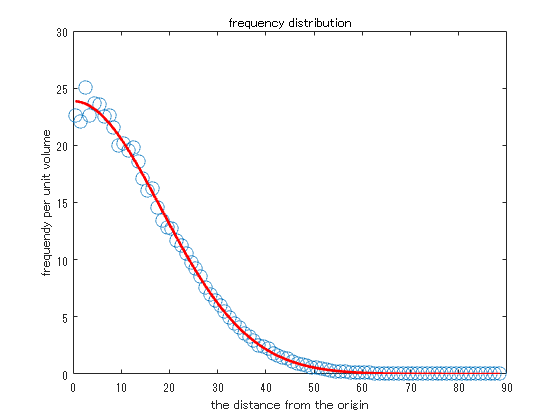


l = h.BinWidth;
x0 = 1:1:h.NumBins;
x0 = l * (x0-0.5);
y0 = h.Values/(2*pi)./x0/l;
plot(x0, y0, 'o', MarkerSize=10)
D = 1/6;
y1 = (N/(4*pi*D*T)) * exp(-x0.*x0/(4*D*T));
hold on
plot(x0, y1, 'r', LineWidth=2)
xlabel('the distance from the origin')
ylabel('frequendy per unit volume')
title('frequency distribution')
hold off

### 拡散現象の時空パターン

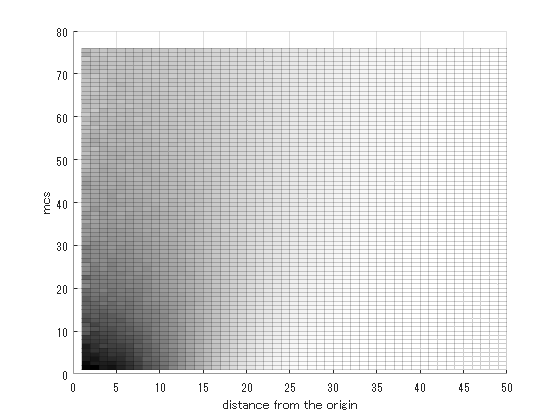

tiledlayout(1,1)
surf(xh2(25:100,1:50),EdgeAlpha=0.2)
%surf(xh2(25:100,1:50),'FaceAlpha',0.5,EdgeColor="flat")
xlabel('distance from the origin')
ylabel('mcs')
%colormap(turbo) 
colormap(flipud(gray)) 
%shading interp    % interpolate colors across lines and faces
%view(0,0)
view(0,90)

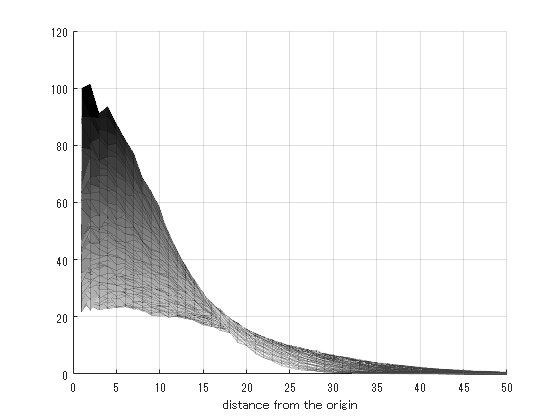


surf(xh2(25:100,1:50),EdgeAlpha=0.2)
%surf(xh2(25:100,1:50),'FaceAlpha',0.5,EdgeColor="flat")
xlabel('distance from the origin')
ylabel('mcs')
%colormap(turbo) 
colormap(flipud(gray)) 
%shading interp    % interpolate colors across lines and faces
view(0,0)

## 3次元 random walk

最後に3次元空間をランダムウォークする粒子の軌跡を見てみよう。

時刻 $t$ における粒子の座標 $(x(t),y(t),z(t))$ を次式に従って更新する。


$$x(t+1) = x(t) + r_x(t)\\
y(t+1) = y(t) + r_y(t)\\
z(t+1) = z(t) + r_z(t)$$


ただし、 $\left(x(0), y(0), z(0))=(0, 0, 0)$、 $r_x(t), r_y(t), r_z(t)$ は $-1$からから $+1$までの一様乱数とする。

Q4. 軌跡 $\left(x(t), y(t), z(t))$を $0\leq t \leq 1000$の範囲でプロットせよ。

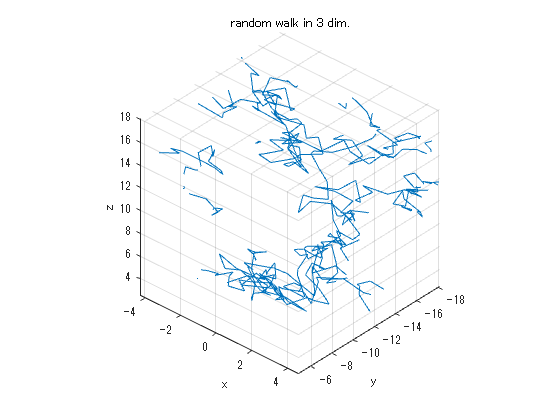

%random walk 
T = 1000;
rx = 2*(rand(1, T)-0.5);
ry = 2*(rand(1, T)-0.5);
rz = 2*(rand(1, T)-0.5);
wx = [0 cumsum(rx,2)];
wy = [0 cumsum(ry,2)];
wz = [0 cumsum(rz,2)];

%plot a time series 
plot3(wx, wy, wz)
title('random walk in 3 dim.')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

% 図の縦横比を１：１にする
pbaspect([1 1 1])

## 付録

### ２次元ランダムウォークするN粒子の空間分布 (散布図)とガウス分布によるフィッティング（動画作成用）

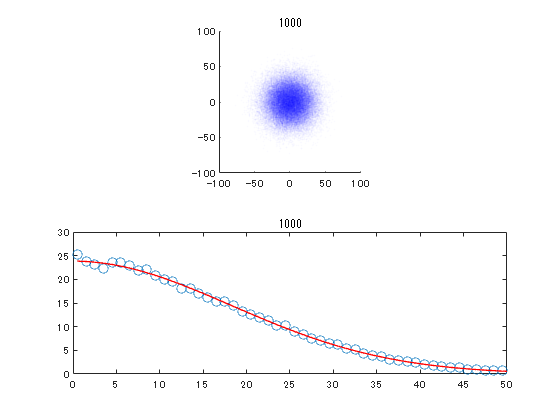

clf;
N = 50000;
T = 1000;
px = zeros(1,N);
py = zeros(1,N);

v = VideoWriter('randomwalk.avi');
% v.FrameRate = 2;
open(v)

%hold on 

for j = 1:1:T+1
    if rem(j,10)==1
        tiledlayout(2,1) % Requires R2019b or later
        nexttile
        s=scatter(px, py, 1,'blue', 'filled');
        s.AlphaData = 0.2;
        s.MarkerFaceAlpha = 0.02;
        xlim([-100 100])
        ylim([-100 100])
        pbaspect([1 1 1])
        title(j-1)

        nexttile
        ds = sqrt(px.*px + py.*py);
        binwidth = 1;
        nbins = [0:binwidth:T];
        h2 = histcounts(ds, nbins);
        x2 = binwidth * ([1:binwidth:T]-0.5*binwidth);
        y2 = h2/(2*pi)./x2/binwidth;
        plot(x2, y2, 'o', MarkerSize=7);
        xlim([0 50])
        %ylim([0 10000])
        D = 1/6;
        y2p = (N/(4*pi*D*j)) * exp(-x2.*x2/(4*D*j));
        hold on
        plot(x2, y2p, 'r', LineWidth=1);
        title(j-1);
        hold off
        frame = getframe(gcf);
        writeVideo(v,frame)
    end
    px = px + 2*(rand(1, N)-0.5);
    py = py + 2*(rand(1, N)-0.5);
end

close(v);

### ２次元ランダムウォーク：ガウス分布へのフィッティング

%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( x0, y0 );

% 近似タイプとオプションを設定します。
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [238.678705887011 1 16.3007571199205];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Gauss1:
     fitresult(x) =  a1*exp(-((x-b1)/c1)^2)
     係数 (95% の信頼限界):
       a1 =       23.56  (23.17, 23.96)
       b1 =      0.5643  (-0.3493, 1.478)
       c1 =       25.39  (24.59, 26.19)

gof = フィールドをもつ struct :
           sse: 12.6628
       rsquare: 0.9978
           dfe: 86
    adjrsquare: 0.9978
          rmse: 0.3837


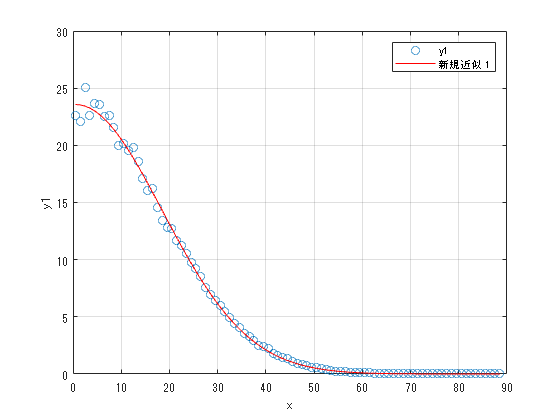


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData,'o' );
legend( h, 'y1', '新規近似 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
ylabel( 'y1', 'Interpreter', 'none' );
grid on